% Sizing to TO
clc; clear all
close all

% Pre-script
list_factory = fieldnames(get(groot,'factory'));
index_interpreter = find(contains(list_factory,'Interpreter'));
for i = 1:length(index_interpreter)
    default_name = strrep(list_factory{index_interpreter(i)},'factory','default');
    set(groot, default_name,'latex');
end


W_to_max = 9159; % Maximum Gross Takeoff Weight (N)
We = 4531 % Empty Weight (N)

We = 4531

S = convlength(convlength(174, "ft", "m"), "ft", "m") % Average wing area from STAMPED in m^2

S = 16.1651

S_to_max = 500 % Max takeoff distance from CS 22 (m)

S_to_max = 500

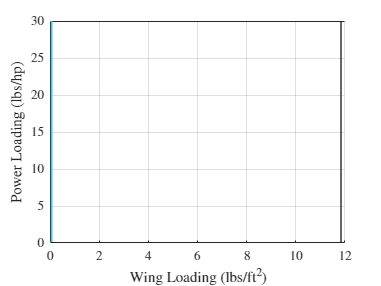

S_tog_max = S_to_max / 1.6; % From Fig 3.4 pg 96, S_tog from S_to

% convert Si units to english units for English equations
W_to_max_eng = convforce(W_to_max, "N", "lbf");        %Max takeoff weight in lbs from initial sizing
We_eng = convforce(We, "N", "lbf");  ;                %empty weight in lbs
S_eng = convlength(convlength(S,"m","ft"),"m","ft");                %Average wing area from STAMPED in ft^2
S_to_max_eng = convlength(S_to_max,"m","ft");       %Max takeoff distance in meters from CS 22 (= 500 m)
S_tog_max_eng = convlength(S_tog_max,"m","ft");    %From Fig 3.4 pg 96, S_tog from S_to

% compute points
TOP23 = 86;                 %Eq 3.6, in lbs^2/(ft^2hp)
CL_max_to = linspace(1.4,2,5);

% compute effective atmospheric density ratio for ISA 1000ft + 10C
sigma_10c = .966;
[~, ~, ~, rho_SL] = atmosisa(convlength(1000,"ft","m")); % atmospheric density at Sea Level
[~, ~, ~, rho_1000] = atmosisa(convlength(1000,"ft","m")); % atmospheric density at 1000ft ASL
simga_1000ft = rho_1000 /rho_SL;
sigma = sigma_10c * simga_1000ft; % atmospheric density ratio (1 at sea level)

WS_to_eng = linspace(We_eng/S_eng, W_to_max_eng*1.5/S_eng, 500);

for i = 1:5
    WP_to_eng(:,i) = TOP23 * sigma * CL_max_to(:,i) ./ (WS_to_eng);
end

hp2W = 745.699872; % conversion factor: horse-power -> Watt
lbf2N = convforce(1,"lbf","N"); % conversion factor: lbf -> N

conv_W2P_eng2SI = lbf2N/hp2W;

WP_to = WP_to_eng * conv_W2P_eng2SI;
WS_to = WS_to_eng * conv_W2P_eng2SI;

hold on;
for i = 1:5
    plot(WS_to, WP_to(:,i))
end

hold on
xline(W_to_max_eng/S_eng, LineWidth=1.5)
grid on
ylabel('Power Loading (lbs/hp)', 'Interpreter', 'latex'), xlabel('Wing Loading (lbs/ft$^2$)', 'Interpreter', 'latex')
%legend('$C_{LTO}=1.4$','$C_{LTO}=1.7$','$C_{LTO}=2.0$','Wing Loading at MTOW', 'Interpreter', 'latex')

area(WS_to, WP_to(:,1), 30);

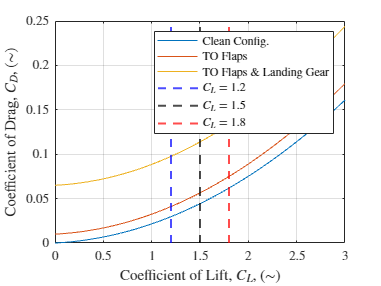


%% Climb sizing
% Drag Polars
clc
Swet=480;   % Estimate from fig 3.22
cf=.005;
AR=22;       % DG1000
e=.9;
CL_max=linspace(1.2,1.8,3);
CL=linspace(0,3,50);
f_graph=Swet*(CL/46.5-(CL/(pi*AR*e)));
f=Swet*(CL_max/46.5-(CL_max/(pi*AR*e)));
Cd_clean=f_graph/Swet+CL.^2/(pi*AR*.9);    %clean
Cd_fl=.01+f_graph/Swet+CL.^2/(pi*AR*.85);       %Takeoff flaps
Cd_flla=.065+f_graph/Swet+CL.^2/(pi*AR*.8);    %Takeoff flaps gear down
figure
plot(CL,Cd_clean,CL,Cd_fl,CL,Cd_flla)
xlabel('Coefficient of Lift, $C_L$, $(\sim)$', 'Interpreter', 'latex'), ylabel('Coefficient of Drag, $C_D$, $(\sim)$', 'Interpreter', 'latex')
xline(CL_max(:,1),'b--', LineWidth=1.5), xline(CL_max(:,2),'k--', LineWidth=1.5), xline(CL_max(:,3),'r--', LineWidth=1.5)
grid on
legend('Clean Config.','TO Flaps','TO Flaps \& Landing Gear','$C_L=1.2$','$C_L=1.5$','$C_L=1.8$', 'Interpreter', 'latex')



%% Climb  (dh/dt)
clc;
rho = .0023; 
sigma = .9761;
WS_climb = linspace(We_eng/S_eng,W_to_max_eng/S_eng,10);
eta_p = .8;
RCP = [295 600 1200]/33000;
Cdo = f(:,2)/Swet+.01;    %clean plus flaps
Vclimb = sqrt(2*WS_climb/(rho*CL_max_to(:,3)));      %CLmax with flaps in best case 
CL_CD_32max = 1.345*(AR*e)^.75/(Cdo^.25);
RCP_max = eta_p/WP_to3(:,250)-sqrt(W_to_max_eng/S_eng)/(19*sqrt(sigma)*CL_CD_32max);

Unrecognized function or variable 'WP_to3'.

W_P_parameters = eta_p./(sqrt(W_to_max_eng/S_eng)./(19*sqrt(sigma)*CL_CD_32max)+RCP);


